# Continuation of quasiperiodic invariant tori

We consider a four-node network of oscillators coupled through linear spring. The damping of the first node is of van der pol type and this node subjects to external harmonic forcing. The equation of motion of this system is given as follows


$$\ddot{u}_1+(\epsilon u_1^2-1)\dot{u}_1+3u_1-u_2-u_4=\epsilon a\cos\Omega t,\\
\ddot{u}_2+0.8\dot{u}_2-u_1+4u_2-u_3-u_4=0,\\
\ddot{u}_3+0.8\dot{u}_3-u_2+2u_3=0,\\
\ddot{u}_4+0.8\dot{u}_4-u_1-u_2+3u_4=0
$$


More details about this model can be found in [1]. In this demo, we will perform

- continuation of periodic orbits with varied $\Omega$,

- continuation of torus (TR) bifurcation with varied $a$ and $\Omega$,

- continuation of tori from TR point,

- continuation of tori with fixed rotation number $\varrho$,

- continuation of tori with varied rotation number $\varrho$. 

[1] Yu Mao and Harry Dankowicz. Topology-dependent Excitation Response of

Networks of Linear and Nonlinear Oscillators

## Construct an of initial periodic orbit 

% pnames = [ om a ]
p0 = [ 2; 0.4 ];
T  = 2*pi/p0(1);
[~,x0]  = ode45(@(t,x) net(t,x,p0), 0:1000*T, zeros(8,1)); % Approximate periodic orbit of reduced system
[t0,x0] = ode45(@(t,x) net(t,x,p0), linspace(0,T,200), x0(end,:));

## Continuation of periodic orbit

prob = coco_prob();
prob = coco_set(prob, 'ode', 'autonomous', false);
prob = coco_set(prob, 'cont', 'NAdapt', 5, 'h_max', 5);
prob = coco_set(prob, 'coll', 'NTST', 20);
prob = ode_isol2po(prob, '', @net, ... % @lang_DFDX, @lang_DFDP
  t0, x0, {'Om2','f'}, p0);
[data, uidx] = coco_get_func_data(prob, 'po.orb.coll', 'data', 'uidx');
maps = data.coll_seg.maps;
prob = coco_add_func(prob, 'OmegaT', @OmegaT, @OmegaT_du, [], 'zero',...
    'uidx', [uidx(maps.T_idx), uidx(maps.p_idx(1))]);

fprintf('\n Run=''%s'': Continue family of periodic orbits.\n', ...
  'po');


 Run='po': Continue family of periodic orbits.



coco(prob, 'po', [], 1, {'Om2','po.period'}, [1.9 2.1]);


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.58e-02  2.75e+01    0.0    0.0    0.0
   1   1  9.80e-01  3.03e+00  1.23e-03  2.45e+01    0.0    0.0    0.0
   2   1  1.00e+00  5.79e-01  3.95e-05  2.40e+01    0.0    0.0    0.0
   3   1  1.00e+00  1.88e-02  4.08e-08  2.40e+01    0.0    0.0    0.0
   4   1  1.00e+00  1.95e-05  4.53e-14  2.40e+01    0.0    0.0    0.0
   5   1  1.00e+00  2.01e-11  8.28e-15  2.40e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           Om2    po.period
    0  00:00:00   2.3961e+01      1  EP      2.0020e+00   3.1385e+00
   10  00:00:01   2.6298e+01      2          2.0013e+00   3.1395e+00
   20  00:00:03   2.7744e+01      3          2.0000e+00   3.1416e+00
   30  00:00:04   2.6980e+01      4          1.9986e+00   3.1438e+00
   40  00:00:05   2.3970e+01      5          1.9975e+00   3.1455e+00
   50  00:00:06   1.9321

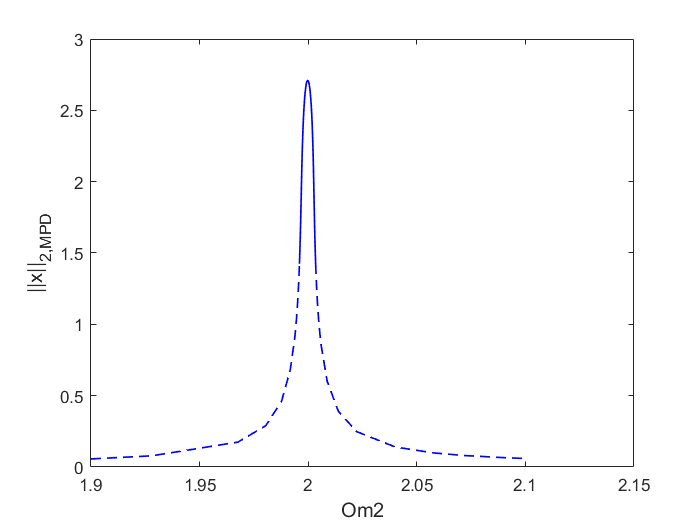


figure; coco_plot_bd('po')

## Continuation of TR bifurcation points

bd     = coco_bd_read('po');
TRlabs = coco_bd_labs(bd, 'TR');
TRlab  = max(TRlabs);
prob = coco_prob();
prob = coco_set(prob, 'ode', 'autonomous', false);
prob = coco_set(prob, 'cont', 'NAdapt', 5, 'h_max', 5);
prob = ode_po2TR(prob, '', 'po', TRlab);
[data, uidx] = coco_get_func_data(prob, 'po.orb.coll', 'data', 'uidx');
maps = data.coll_seg.maps;
prob = coco_add_func(prob, 'OmegaT', @OmegaT, @OmegaT_du, [], 'zero',...
    'uidx', [uidx(maps.T_idx), uidx(maps.p_idx(1))]);

fprintf('\n Run=''%s'': Continue family of TR points.\n', ...
  'po_TR');


 Run='po_TR': Continue family of TR points.



coco(prob, 'po_TR', [], 1, {'f','Om2','po.period'}, [0.4 6]);


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.40e-07  1.83e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE             f          Om2    po.period
    0  00:00:00   1.8301e+01      1  EP      4.0000e-01   2.0034e+00   3.1362e+00
   10  00:00:05   1.7990e+01      2          1.1530e+00   2.0111e+00   3.1243e+00
   20  00:00:11   1.7981e+01      3          3.0565e+00   2.0301e+00   3.0950e+00
   23  00:00:13   1.9547e+01      4  EP      6.0000e+00   2.0594e+00   3.0510e+00


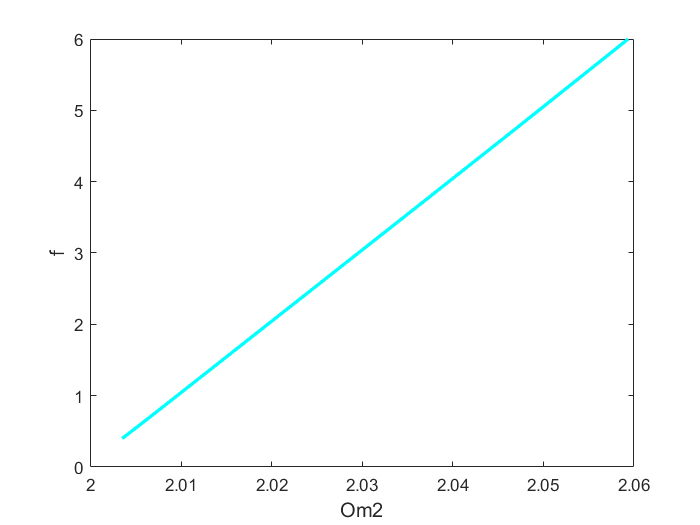

figure;
coco_plot_bd('po_TR','Om2','f')

## Continuation of tori from TR point

bd    = coco_bd_read('po_TR');
TRlab = coco_bd_labs(bd, 'EP');
TRlab = max(TRlab);
prob = coco_prob();
prob = coco_set(prob, 'cont', 'NAdapt', 5, 'PtMX', 50, 'h_max', 5,...
    'h_min', 1e-4);
prob = ode_TR2tor(prob, '', 'po_TR', TRlab, 'neg', 1e-8);
fprintf(...
  '\n Run=''%s'': Continue torus from point %d in run ''%s''.\n', ...
  'tr1', TRlab, 'po_TR');


 Run='tr1': Continue torus from point 4 in run 'po_TR'.


coco(prob, 'tr1', [], 1, {'varrho','Om2','om2','om1','f'});


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          4.03e-02  5.80e+01    0.0    0.0    0.0
   1   1  1.00e+00  3.20e-02  5.31e-08  5.81e+01    0.0    0.5    0.1
   2   1  1.00e+00  6.71e-04  7.93e-11  5.81e+01    0.0    0.9    0.1
   3   1  1.00e+00  2.24e-04  8.80e-12  5.81e+01    0.0    1.3    0.2
   4   1  1.00e+00  8.39e-05  1.24e-12  5.81e+01    0.0    1.7    0.2
   5   1  1.00e+00  7.67e-05  1.03e-12  5.81e+01    0.1    2.3    0.3
   6   1  1.00e+00  2.47e-05  1.11e-13  5.81e+01    0.1    2.9    0.4
   7   1  1.00e+00  1.58e-05  4.92e-14  5.81e+01    0.1    3.4    0.4
   8   1  1.00e+00  1.34e-06  1.74e-14  5.81e+01    0.1    3.8    0.5
   9   1  1.00e+00  1.96e-07  1.76e-14  5.81e+01    0.1    4.3    0.5

 STEP      TIME        ||U||  LABEL  TYPE        varrho          Om2          om2          om1            f
    0  00:00:06   5.8067e+01      1  EP     -2.894

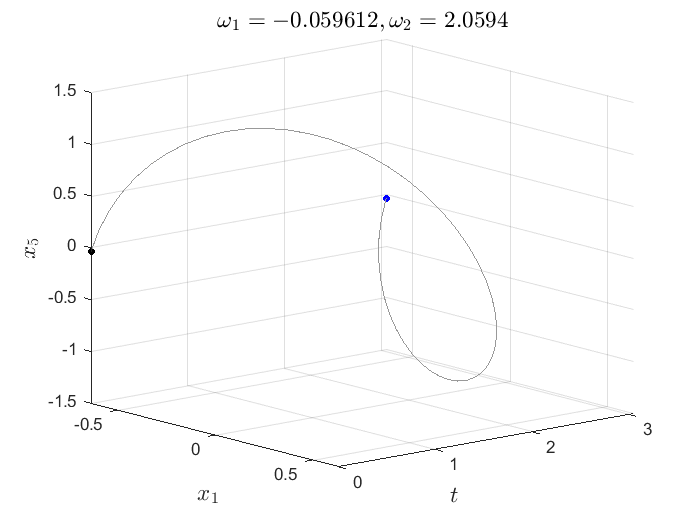

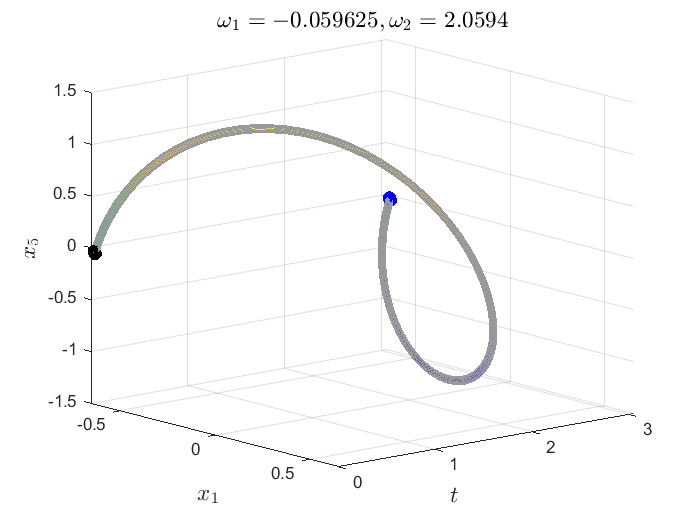

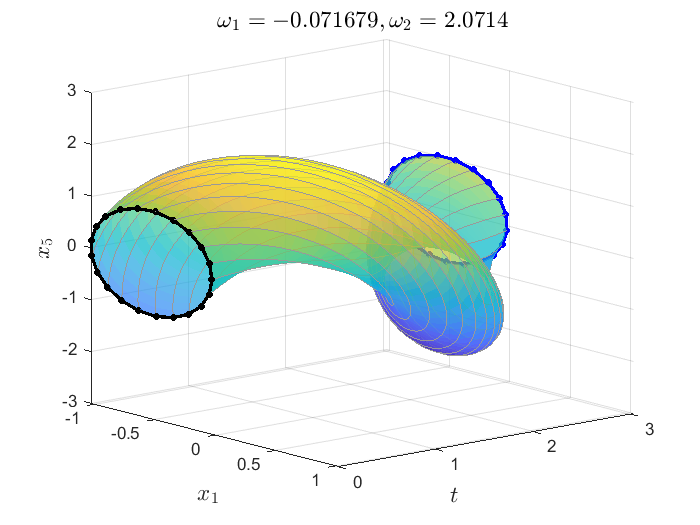

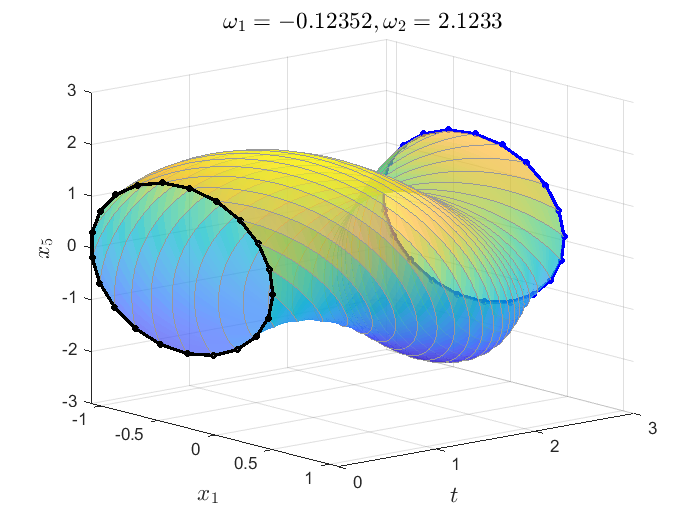

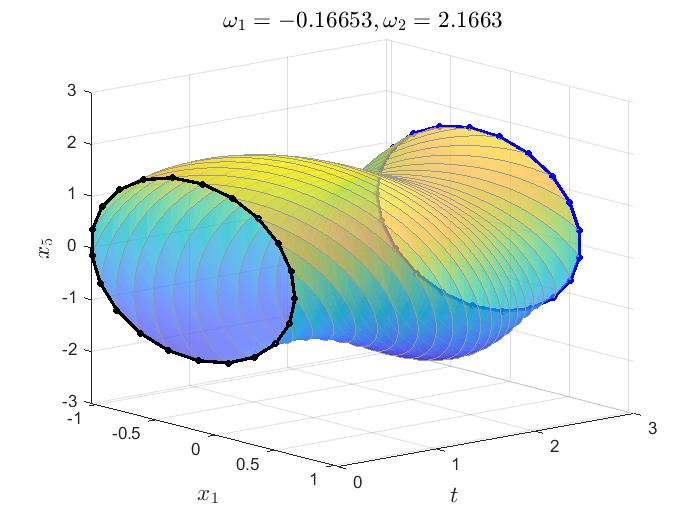

for lab = 4:8
    plot_torus('','tr1',lab,[1 5]); pause(1);
end

## Continuation of torus with fixed $\varrho$

lab  = 7;
prob = coco_prob();
prob = coco_set(prob, 'cont', 'NAdapt', 5, 'PtMX', 100, 'h_max', 50);
prob = ode_tor2tor(prob, '', 'tr1', lab);
fprintf(...
  '\n Run=''%s'': Continue torus from point %d in run ''%s''.\n', ...
  'tr2', lab, 'tr1');


 Run='tr2': Continue torus from point 7 in run 'tr1'.


coco(prob, 'tr2', [], 1, {'f','Om2','om2','om1','varrho'},[0.4 6]);


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          9.79e-14  8.73e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE             f          Om2          om2          om1       varrho
    0  00:00:01   8.7319e+01      1  EP      6.0000e+00   2.1233e+00   2.1233e+00  -1.2352e-01  -5.8173e-02
   10  00:00:22   8.4608e+01      2          1.2976e+00   2.1232e+00   2.1232e+00  -1.2352e-01  -5.8173e-02
   11  00:00:30   8.4527e+01      3  EP      4.0000e-01   2.1232e+00   2.1232e+00  -1.2352e-01  -5.8173e-02


## Continuation of torus with varied $\varrho$

bd  = coco_bd_read('tr2');
lab = coco_bd_labs(bd, 'EP');
lab = max(lab);
prob = coco_prob();
prob = coco_set(prob, 'cont', 'NAdapt', 5, 'PtMX', 100, 'h_max', 50);
prob = ode_tor2tor(prob, '', 'tr2', lab);
fprintf(...
  '\n Run=''%s'': Continue torus from point %d in run ''%s''.\n', ...
  'tr3', lab, 'tr2');


 Run='tr3': Continue torus from point 3 in run 'tr2'.


coco(prob, 'tr3', [], 1, {'Om2','om2','om1','varrho','f'},[2.0 2.1233]);


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          9.47e-14  8.45e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           Om2          om2          om1       varrho            f
    0  00:00:01   8.4526e+01      1  EP      2.1232e+00   2.1232e+00  -1.2352e-01  -5.8173e-02   4.0000e-01
   10  00:00:26   8.4449e+01      2          2.0455e+00   2.0455e+00  -4.5792e-02  -2.2386e-02   4.0000e-01
   20  00:00:55   8.4277e+01      3          2.0189e+00   2.0189e+00  -1.9163e-02  -9.4918e-03   4.0000e-01
   30  00:01:25   8.2035e+01      4          2.0061e+00   2.0061e+00  -6.1813e-03  -3.0812e-03   4.0000e-01
   40  00:01:54   7.3578e+01      5          2.0040e+00   2.0040e+00  -3.9070e-03  -1.9496e-03   4.0000e-01
   50  00:02:24   6.4572e+01      6          2.0035e+00   2.0035e+00  -3.4992e-03  -1.7465e-03   4.0000e-01
   60  00:03:04   6.3764e+01    

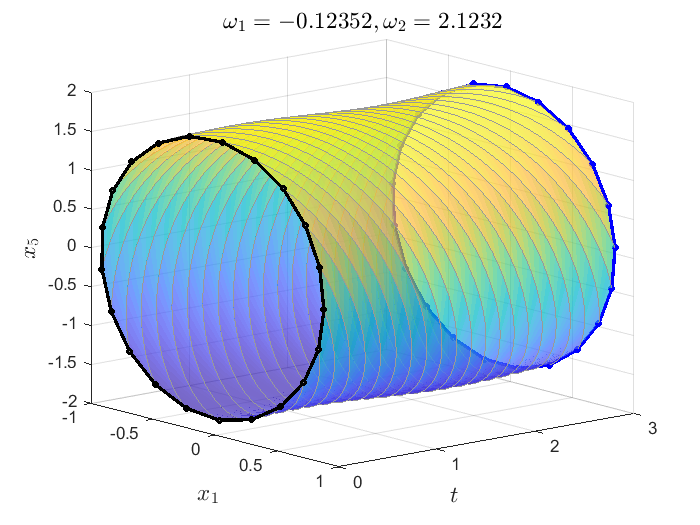

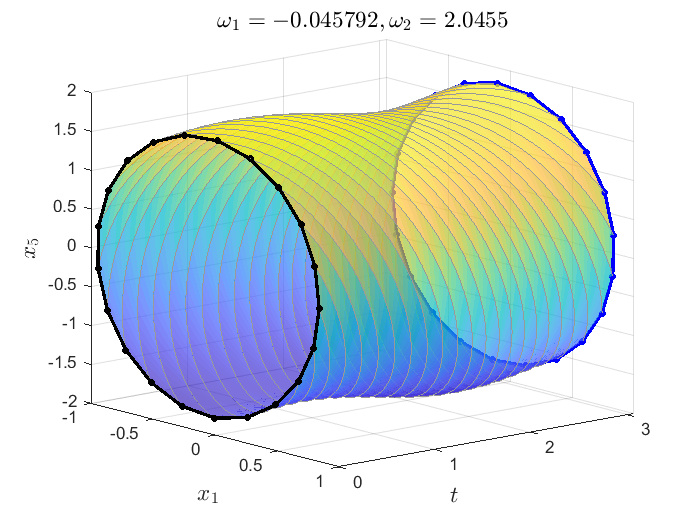

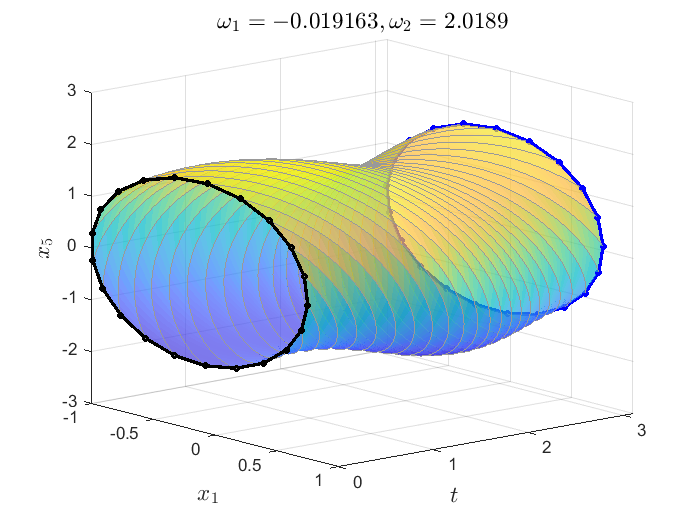

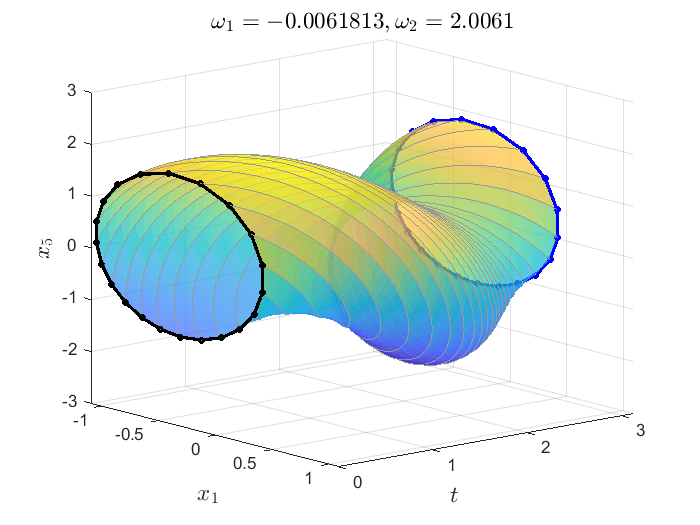

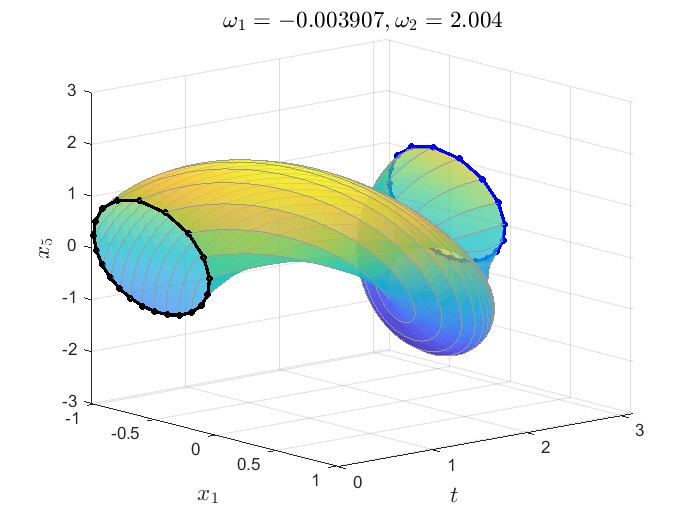

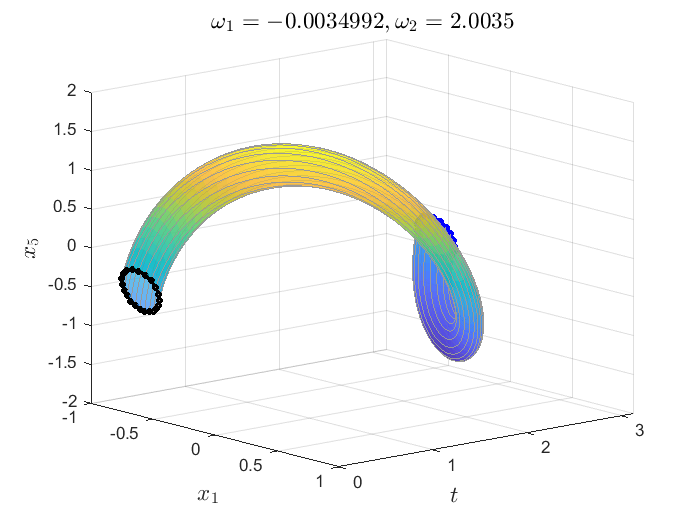

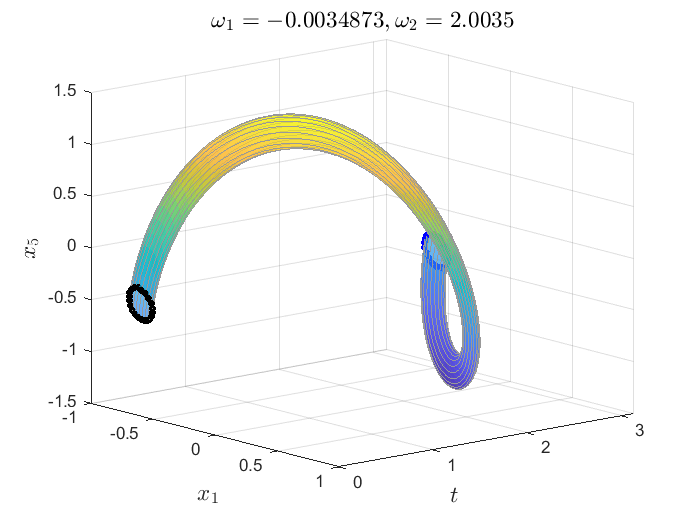

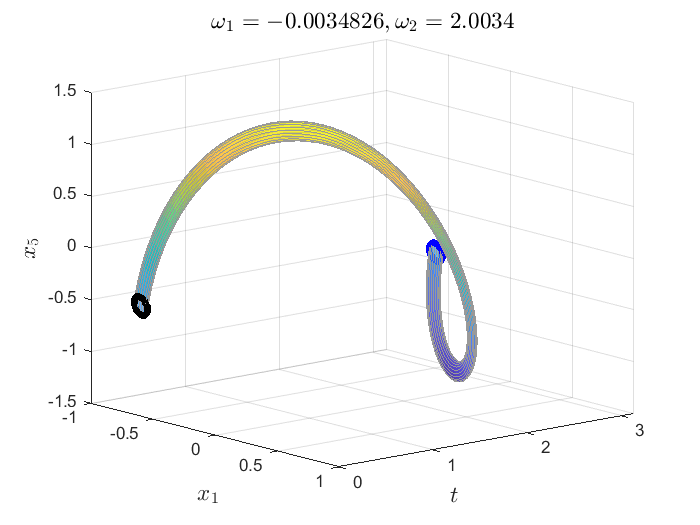

for lab = 1:12
    plot_torus('','tr3',lab,[1 5]); pause(1);
end